Task (a)

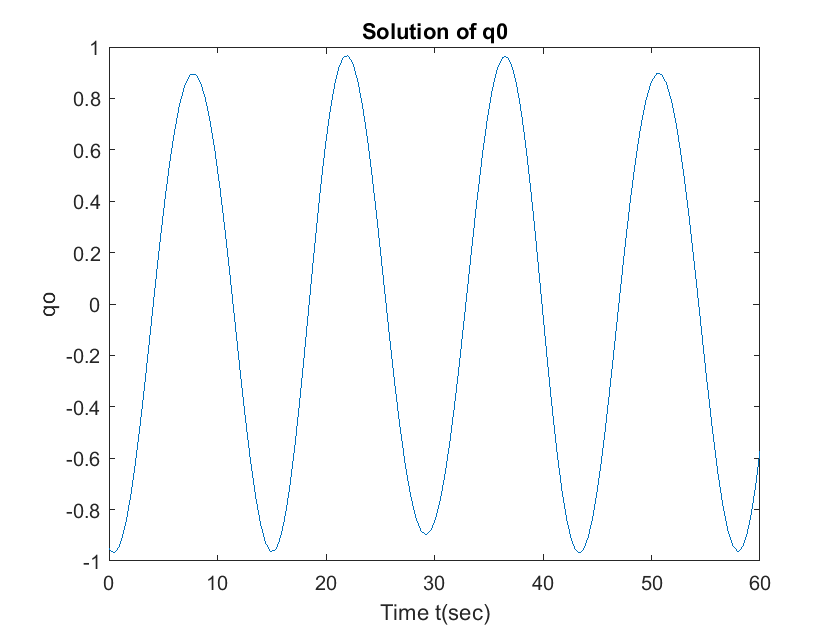

qv0 = [0.1826 0.1826 0.1826];
q0 = -sqrt(1 - norm(qv0)^2);
w0 = [1 0.01 0.02];
y0 = [q0 qv0 w0];
tspan = [0 60];
[t,y] = ode45(@(t,y) spacecraft_dyn(t,y), tspan, y0);
[l,n] = size(y);
qnorm = zeros(l,1);
qvnorm = zeros(l,1);
omega = zeros(l,1);
for i = 1:l
    qnorm(i) = norm(y(i,1:4));
    qvnorm(i) = norm(y(i,2:4));
    omega(i) = norm(y(i,5:7));
end

plot(t,y(:,1))
title('Solution of q0');
xlabel('Time t(sec)');
ylabel('qo');
hold off

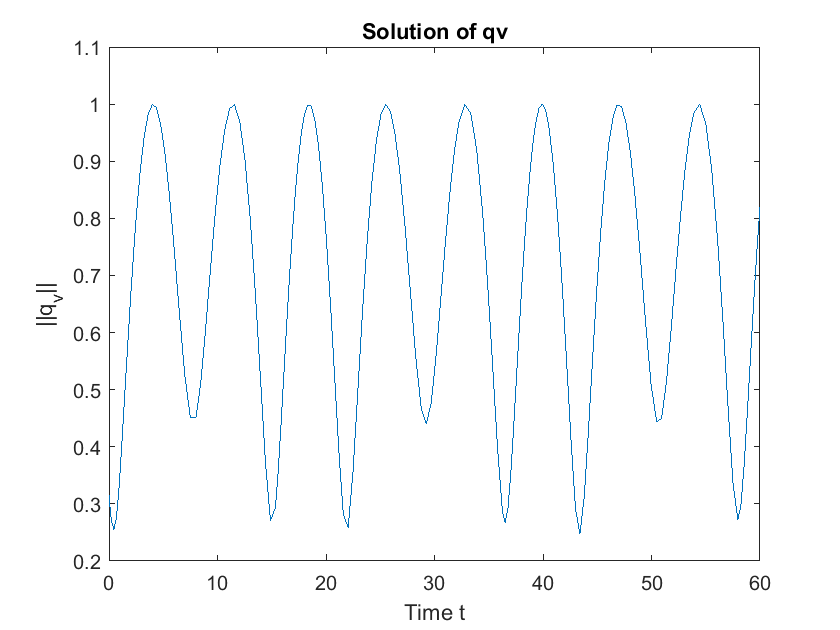


plot(t,qvnorm)
title('Solution of qv');
xlabel('Time t');
ylabel('||q_v||');

hold off

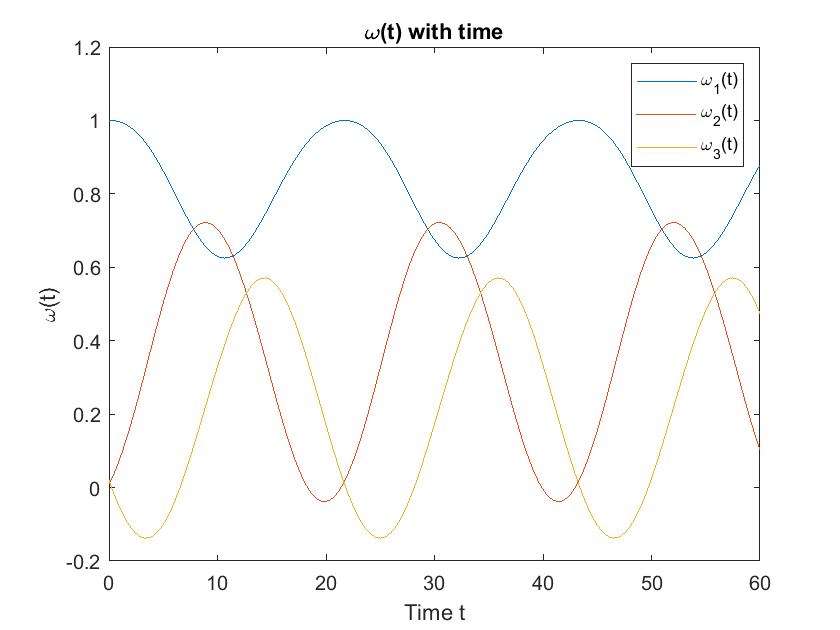

plot(t,y(:,5))
title('\omega(t) with time');
xlabel('Time t');
ylabel('\omega(t)');
hold on
plot(t,y(:,6))
% title('Solution of omega2');
% xlabel('Time t');
% ylabel('\omega 2');
hold on
plot(t,y(:,7))
% title('Solution of omega3');
% xlabel('Time t');
% ylabel('\omega 3');
legend('\omega_1(t)','\omega_2(t)','\omega_3(t)')

hold off

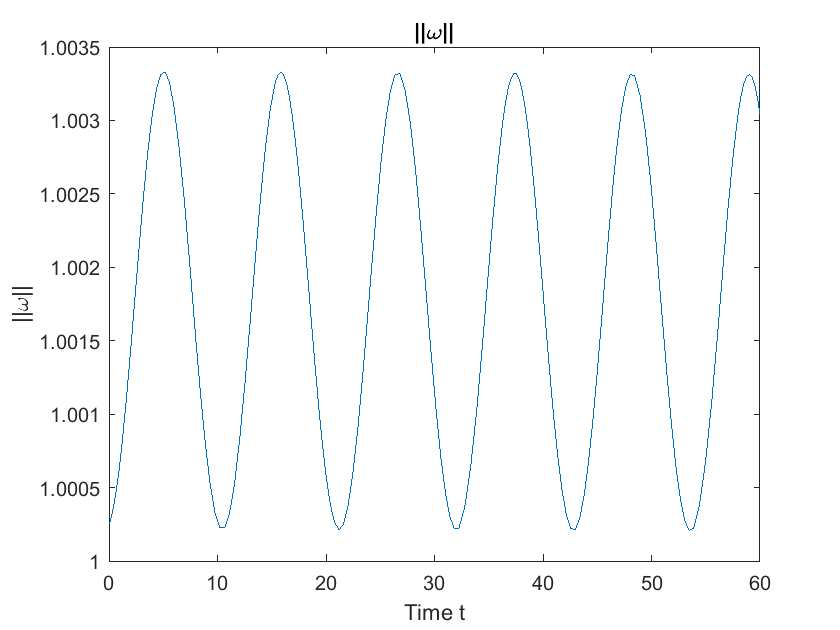

plot(t,omega)
title('||\omega||');
xlabel('Time t');
ylabel('||\omega||');

hold off

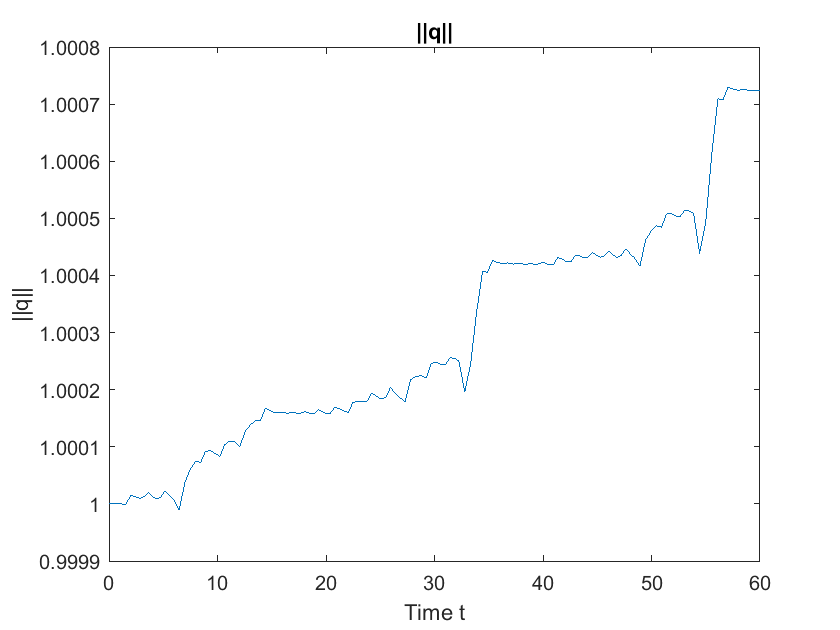

plot(t,qnorm)
title('||q||');
xlabel('Time t');
ylabel('||q||');

Task(b)

NOW USING CONTROL GIVEN

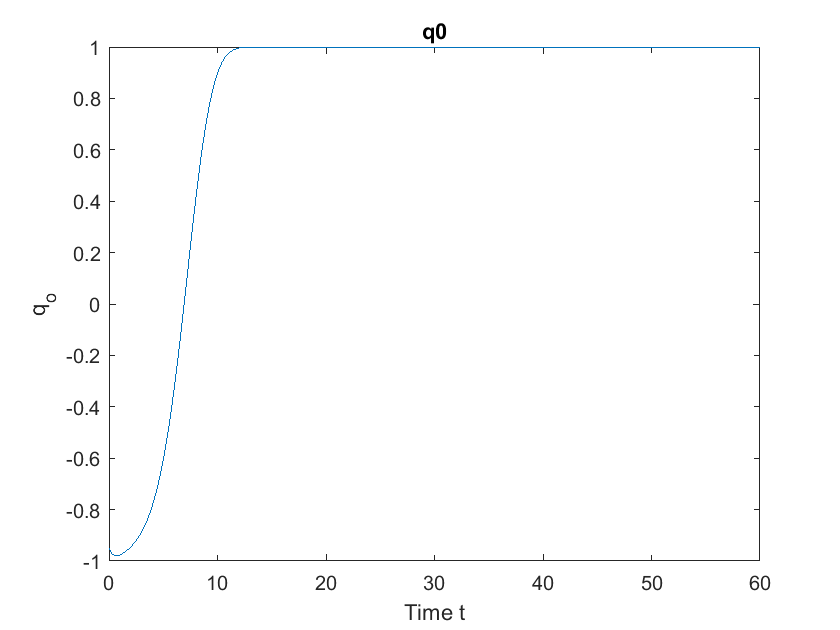

w1 = [1 0.2 0.3];
y1 = [q0 qv0 w1];
J = [20 1.2 0.9; 1.2 17 1.4; 0.9 1.4 15];
kw = 20;
kp = 18;
[t,y] = ode45(@(t,y) spacecraft_dyn_known_J(t,y), tspan, y1);
[l,n] = size(y);
qnorm = zeros(l,1);
qvnorm = zeros(l,1);
omega = zeros(l,1);
state_norm = zeros(l,1);
u1 = zeros(l,1);
u2 = zeros(l,1);
u3 = zeros(l,1);
for i = 1:l
    wJw = cross(-1*y(i,5:7),mtimes(J,y(i,5:7).'));
    qnorm(i) = norm(y(i,1:4));
    qvnorm(i) = norm(y(i,2:4));
    omega(i) = norm(y(i,5:7));
    state_norm(i) = norm(y(i,2:7));
    u1(i) = -kp*y(i,2)-kw*y(i,5)+ wJw(1);
    u2(i) = -kp*y(i,3)-kw*y(i,6)+ wJw(2);
    u3(i) = -kp*y(i,4)-kw*y(i,7)+ wJw(3);
end

plot(t,y(:,1))
title('q0');
xlabel('Time t');
ylabel('q_o');
hold off

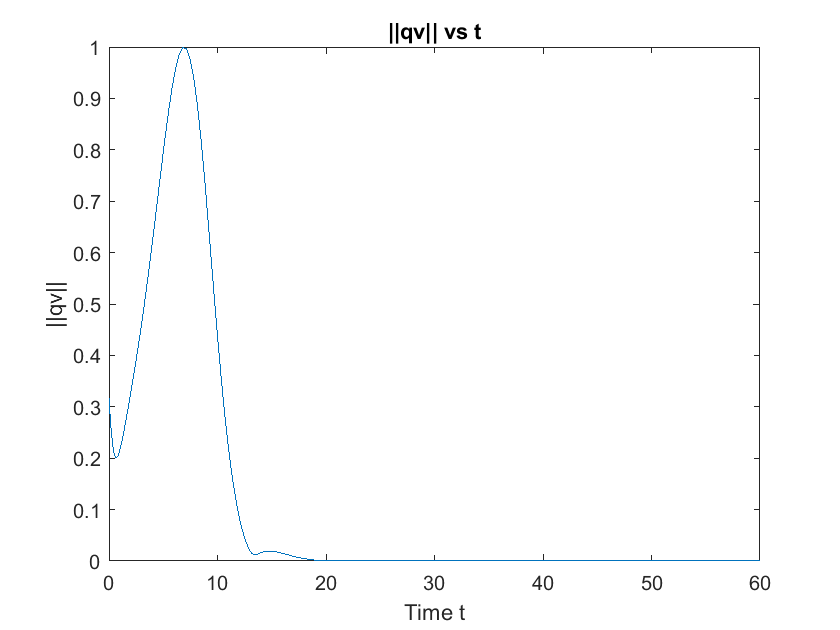


plot(t,qvnorm)
title('||qv|| vs t');
xlabel('Time t');
ylabel('||qv||');

hold off

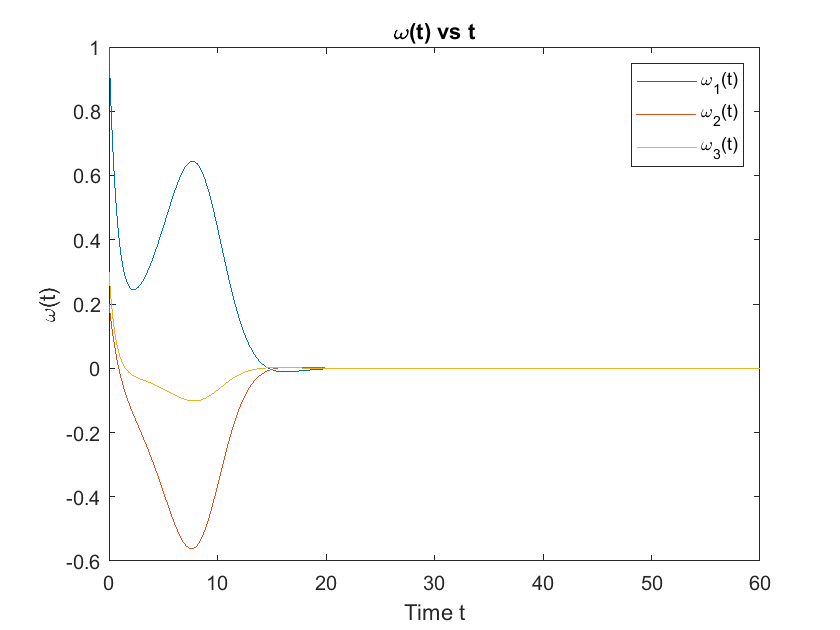

plot(t,y(:,5))
title('\omega(t) vs t');
xlabel('Time t');
ylabel('\omega(t)');
hold on
plot(t,y(:,6))
% title('Solution of omega2');
% xlabel('Time t');
% ylabel('Solution omega2');
hold on
plot(t,y(:,7))
% title('Solution of omega3');
% xlabel('Time t');
% ylabel('Solution omega3');
legend('\omega_1(t)','\omega_2(t)','\omega_3(t)')

hold off

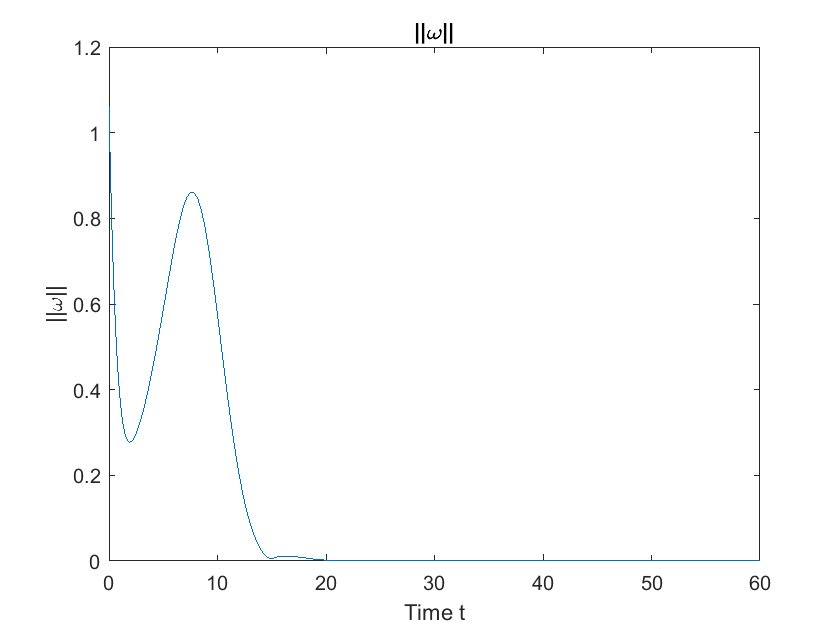

plot(t,omega)
title('||\omega||');
xlabel('Time t');
ylabel('||\omega||');

hold off

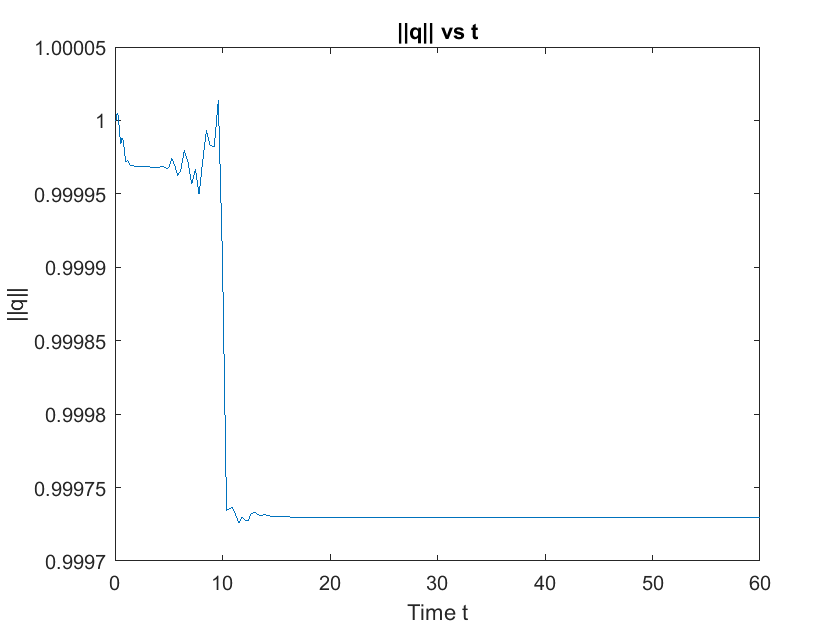

plot(t,qnorm)
title('||q|| vs t');
xlabel('Time t');
ylabel('||q||');

hold off

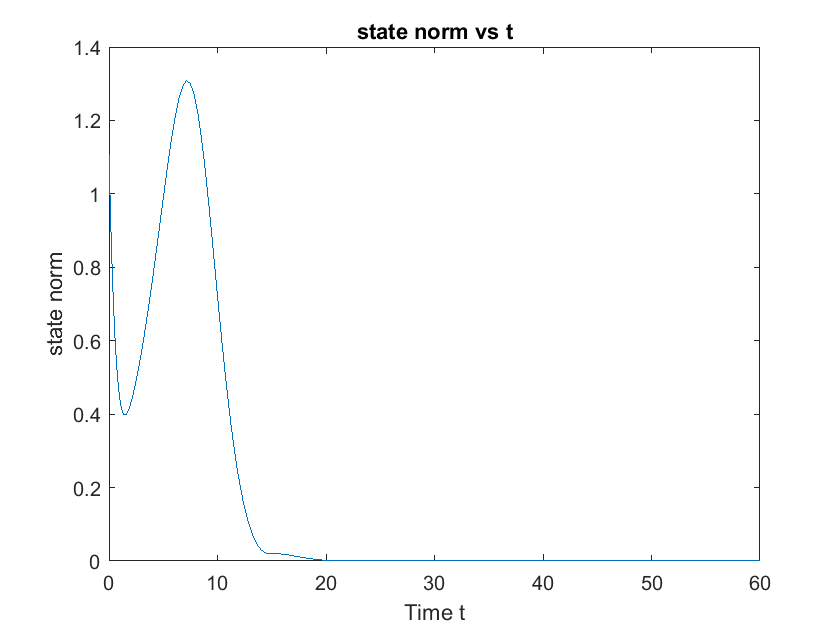

plot(t,state_norm)
title('state norm vs t');
xlabel('Time t');
ylabel('state norm');


hold off

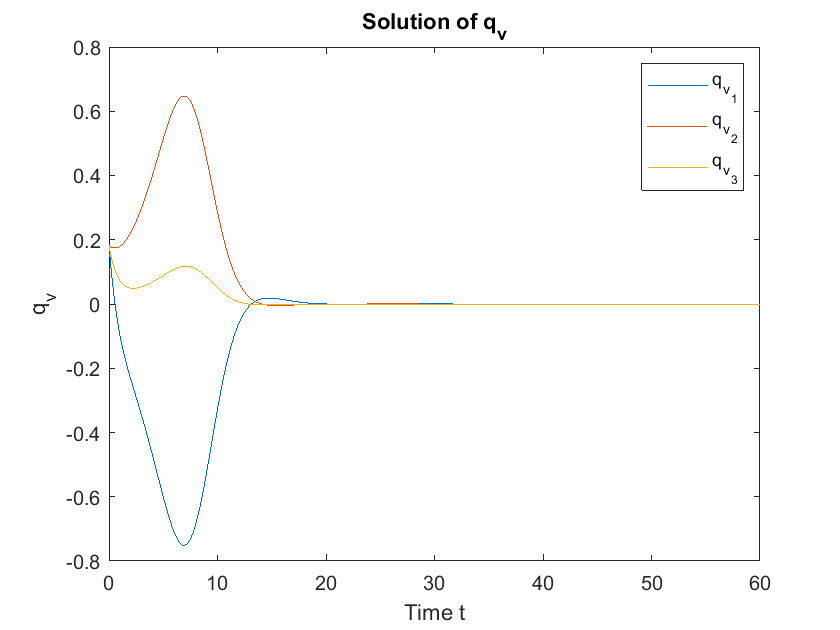

plot(t,y(:,2))
hold on
plot(t,y(:,3))
hold on
plot(t,y(:,4))
title('Solution of q_v');
xlabel('Time t');
ylabel('q_v');
legend('q_{v_1}','q_{v_2}','q_{v_3}')

hold off

plot(t,u1)
hold on
plot(t,u2)
hold on
plot(t,u3)
title('Solution of control inputs');
xlabel('Time t');
ylabel('control u(t)');
legend('u1(t)','u2(t)','u3(t)')

hold off
% 
% title('Solution of u2(t)');
% xlabel('Time t');
% ylabel('control u2(t)');
% 
% hold off
% plot(t,u3)
% title('Solution of u3(t)');
% xlabel('Time t');
% ylabel('control u3(t)');

Task (c) 

%First let's get desired quaternion trajectory from the omega
q0 = 1;
qv0 = [0 0 0];
q0 = [q0 qv0];
tspan = [0 60];
[t,y] = ode45(@(t,y) desire_traj(t,y), tspan, q0);
qd = y;
% plot(t,qd(:,1))
% title('Solution of q0');
% xlabel('Time t');
% ylabel('Solution qo');
% hold off
% plot(t,qd(:,2))
% title('Solution of qv');
% xlabel('Time t');
% ylabel('Solution qv');
% hold off
% plot(t,qd(:,3))
% hold off
% plot(t,qd(:,4))

Now tracking (c)

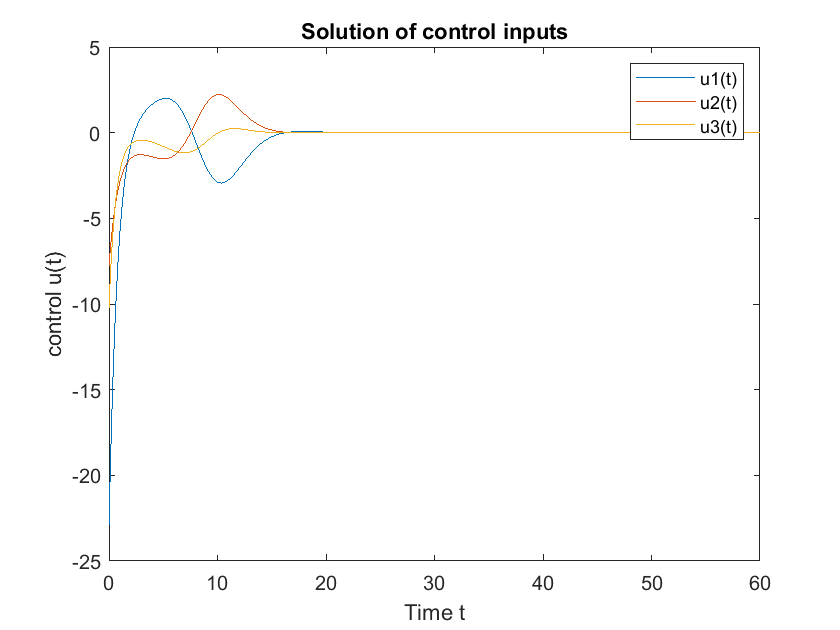

%Solve for S
qv0 = [0.1826 0.1826 0.1826];
q0 = sqrt(1 - norm(qv0)^2);
q = [q0 qv0];
R_q = q_to_R(q);
qd = [1 0 0 0];
R_qd = q_to_R(qd);
Rs = mtimes(R_q,R_qd');
%solve for error dynamics
sv0 = [0.1826 0.1826 0.1826];
s0 = sqrt(1 - norm(sv0)^2);
%initialize w at t=0, then calculate it form del w = w -Rswd
w = [0.41381; -0.2795; 0.867];
wdt0 = [0; 0; 1];
dw0 = (w - mtimes(Rs,wdt0))';
ey0 = [s0 sv0 dw0];
tspan = [0 60];
kw = 29.1;
kp = 30;
[t,y] = ode45(@(t,y) error_dynamics(t,y,kw,kp), tspan, ey0);

[l,n] = size(y);
omega1 = zeros(l,1);
omega2 = zeros(l,1);
omega3 = zeros(l,1);
omegad1 = zeros(l,1);
omegad2 = zeros(l,1);
omegad3 = zeros(l,1);
omegad1dot = zeros(l,1);
omegad2dot = zeros(l,1);
omegad3dot = zeros(l,1);
u1 = zeros(l,1);
u2 = zeros(l,1);
u3 = zeros(l,1);
for i = 1:l
    Rswd = Rs_wd(y(i,1:4),i,l);
    wd = wdes(i,l);
    wddot = wdesdot(i,l);
    omega1(i) = y(i,5) + Rswd(1);
    omega2(i) = y(i,6) + Rswd(2);
    omega3(i) = y(i,7) + Rswd(3);
    omegad1(i) = wd(1);
    omegad2(i) = wd(2);
    omegad3(i) = wd(3); 
    omegad1dot(i) = wddot(1);
    omegad2dot(i) = wddot(2);
    omegad3dot(i) = wddot(3); 
end

for i = 1:l
    Rs = q_to_R(y(i,1:4));
    wd = [omegad1(i);omegad2(i);omegad3(i)];
    wddot = [omegad1dot(i);omegad2dot(i);omegad3dot(i)];
    wc = [omega1(i);omega2(i);omega3(i)];
    wJw = cross(wc,mtimes(J,wc));
    phi = mtimes(mtimes(-y(i,5:7),Rs),wd) + mtimes(Rs,wddot);
    Jphi = mtimes(J,phi);
    u1(i) = -kp*y(i,2)-kw*y(i,5)+ wJw(1)+Jphi(1);
    u2(i) = -kp*y(i,3)-kw*y(i,6)+ wJw(2)+Jphi(2);
    u3(i) = -kp*y(i,4)-kw*y(i,7)+ wJw(3)+Jphi(3);
end
hold off

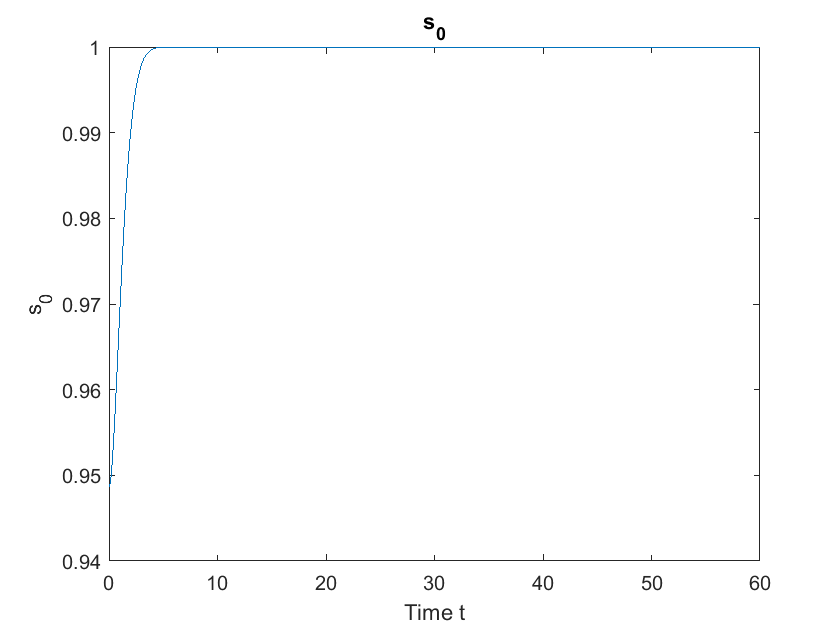

plot(t,y(:,1))
title('s_0');
xlabel('Time t');
ylabel('s_0');

hold off

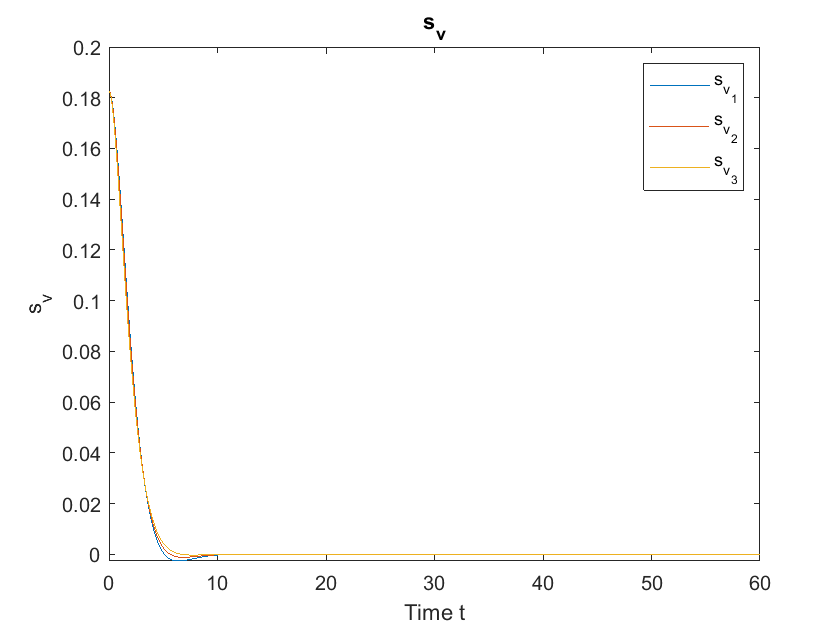

plot(t,y(:,2))
hold on
plot(t,y(:,3))
hold on
plot(t,y(:,4))
title('s_v');
xlabel('Time t');
ylabel('s_v');
legend('s_{v_1}','s_{v_2}','s_{v_3}')

hold off

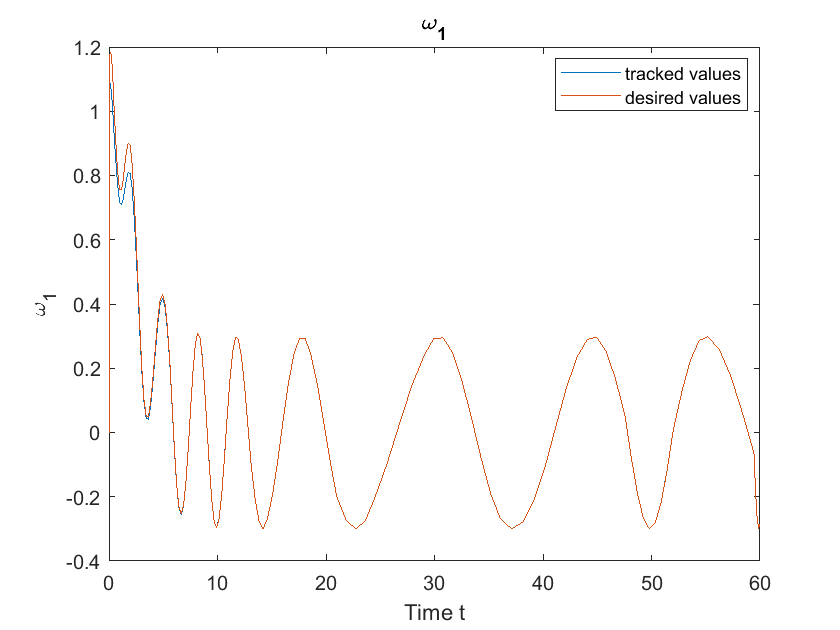

plot(t,omega1)
hold on
plot(t,omegad1)
title('\omega_1');
xlabel('Time t');
ylabel('\omega_1');
legend('tracked values','desired values',"Location","best")

hold off

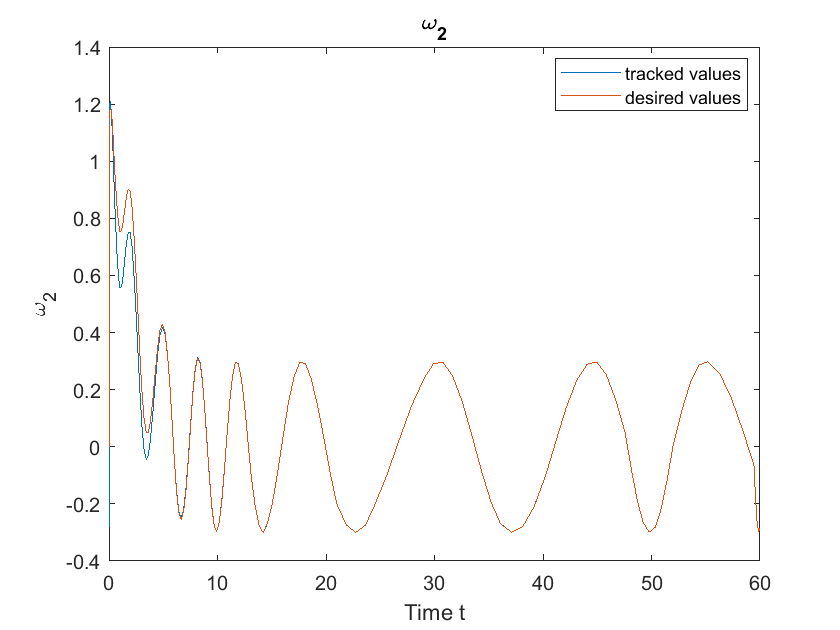

plot(t,omega2)
hold on
plot(t,omegad2)
title('\omega_2');
xlabel('Time t');
ylabel('\omega_2');
legend('tracked values','desired values',"Location","best")

hold off

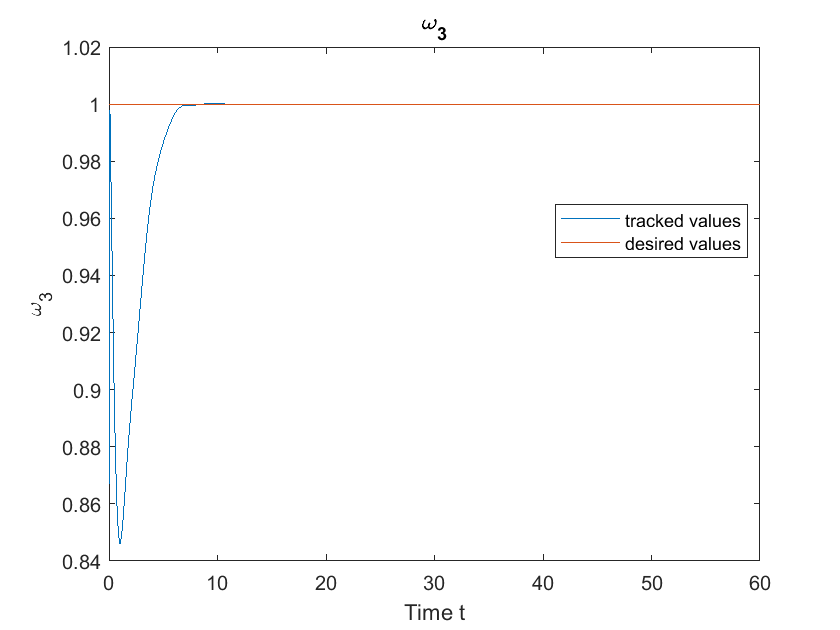

plot(t,omega3)
hold on
plot(t,omegad3)
title('\omega_3');
xlabel('Time t');
ylabel('\omega_3');
legend('tracked values','desired values',"Location","best")


hold off

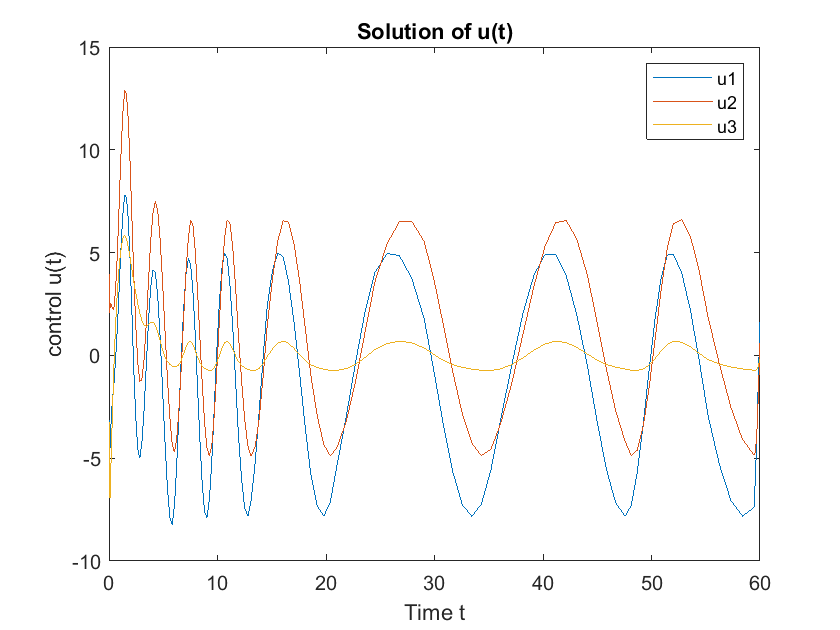

plot(t,u1)
hold on 
plot(t,u2)
plot(t,u3)
title('Solution of u(t)');
xlabel('Time t');
ylabel('control u(t)');
legend('u1','u2','u3')

hold off

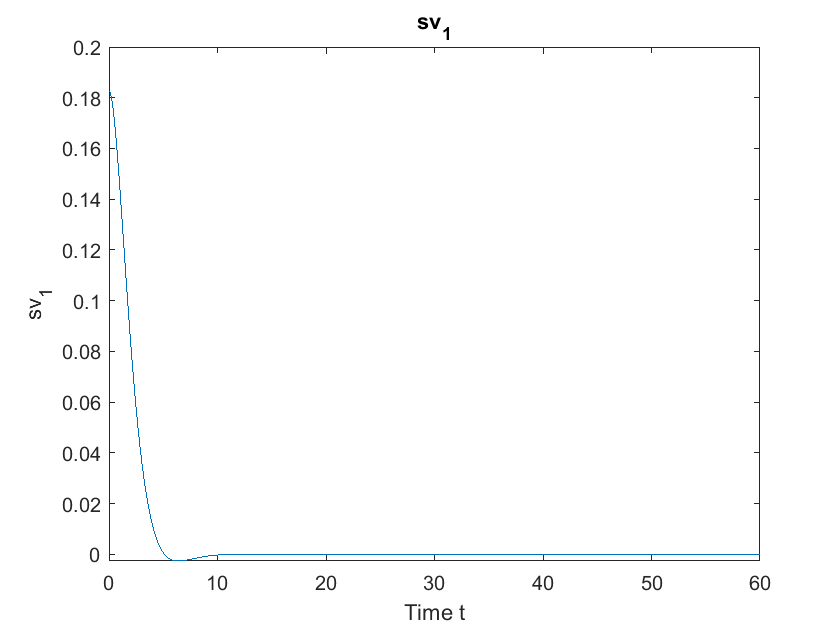

plot(t,y(:,2))
title('sv_1');
xlabel('Time t');
ylabel('sv_1');

hold off

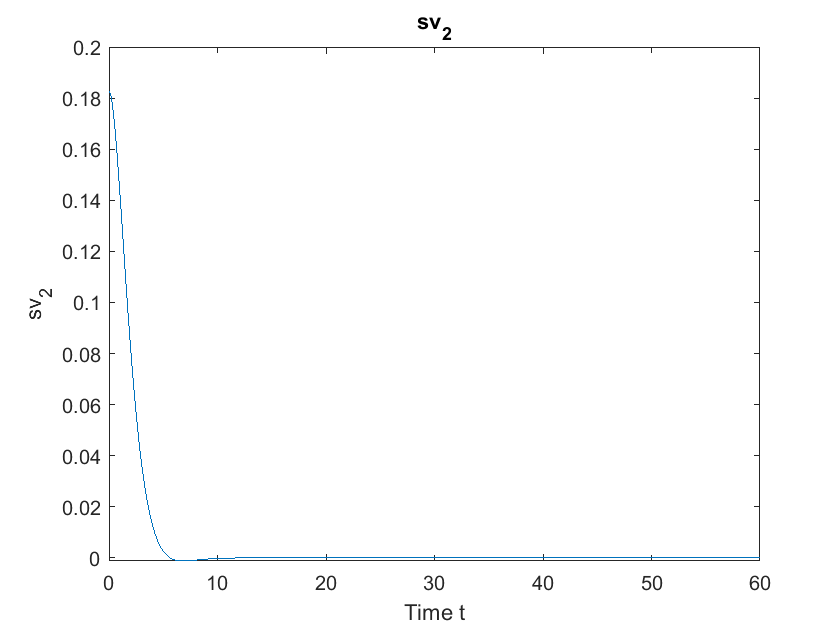

plot(t,y(:,3))
title('sv_2');
xlabel('Time t');
ylabel('sv_2');

hold off

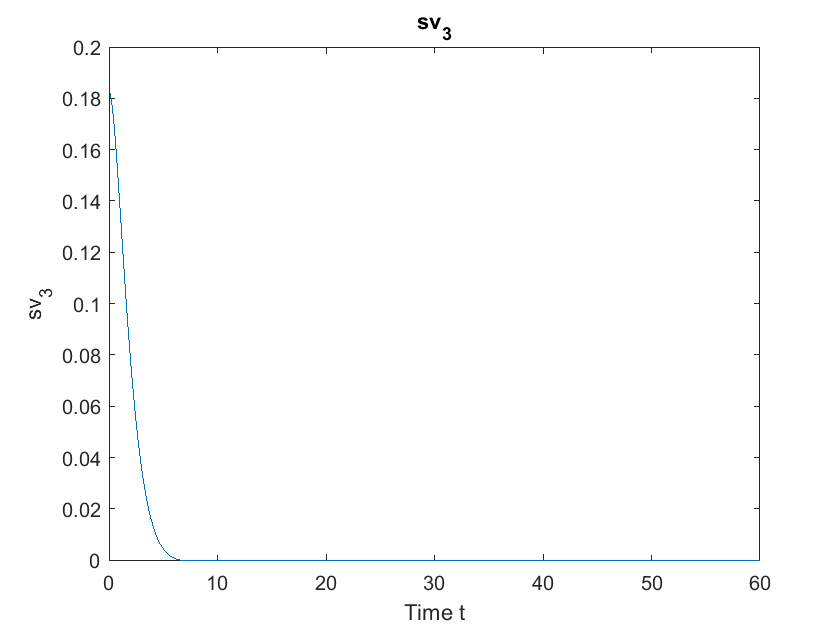

plot(t,y(:,4))
title('sv_3');
xlabel('Time t');
ylabel('sv_3');